y0 =[n_ch3oh_in, n_o2_in, 0, n_h2o_in, n_n2_in]; %initial conditions for ODE: the 0 states that there is no hcho
zspan = [0, 10]; %the ode solver will integrate from 0 to 10 m
option = odeset('Events', @stopEvents); % This stops integrating at a z which we dont know where physical boundaries will tell it to stop

[z, y] = ode45(@reactorODE, zspan, y0)%ODE solver

z =          0
    0.0134
    0.0269
    0.0403
    0.0538
    0.1210
    0.1882
    0.2554
    0.3227
    0.5727


y =   110.0000   60.0000         0   20.0000  810.0000
  109.9999   60.0000    0.0001   20.0001  810.0000
  109.9999   59.9999    0.0001   20.0001  810.0000
  109.9998   59.9999    0.0002   20.0002  810.0000
  109.9998   59.9999    0.0002   20.0002  810.0000
  109.9995   59.9998    0.0004   20.0005  810.0000
  109.9993   59.9996    0.0007   20.0007  810.0000
  109.9990   59.9995    0.0009   20.0010  810.0000
  109.9988   59.9994    0.0012   20.0012  810.0000
  109.9979   59.9989    0.0020   20.0022  810.0001


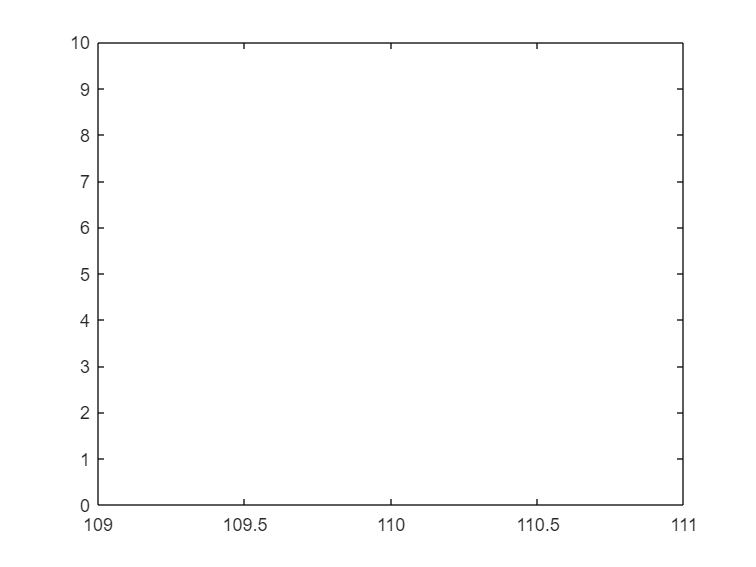


plot(y(1),z)

function dni_dz = reactorODE(z, y)

n_ch3oh = y(1);
n_o2 = y(2);
n_hcho = y(3);
n_h2o = y(4);
n_co = y(5);

%%%% DEFINING CONSTANTS

P_in = 1.6*10^5; %Pressure in
n_T = 1000; % number of moles coming in
alpha = 0.44;
rho_cat = 1500; %in kg/m^3
bed_voidage = 0.4;
R = 8.314; % gas constant
T = 523; %Temperature in Kelvin 
A = 3.14*10^-4; %Area of the tube in m^3

a_ch3oh =1.50 * 10^7; %in mol/kg.s
A_ch3oh = 2.60 * 10^-4; %in atm^-1
A_o2 = 1.42*10^-5; %atm^-1/2
A_h2o = 5.550*10^-7;
a_co = 3.50*10^2; %mol.kg-1.atm-1s-1

%Activation Energies

Ea1 = 86*10^3;
Ea2 = -56.78*10^3;
Ea3 = -60.32*10^3;
Ea4 = -85.45*10^3;
Ea5 = 46.00*10^3;

k = [a_ch3oh, A_ch3oh, A_o2, A_h2o, a_co].* exp(-[Ea1, Ea2, Ea3, Ea4, Ea5] ./ (R*T));% calculating K constants

k_ch3oh = k(1);
K_ch3oh = k(2);
K_o2    = k(3);
K_h2o   = k(4);
k_co    = k(5);

% Defining Partial Pressures NOT SURE IF IT IS CORRECT maybe we need to
% make P vary

P_ch30h = n_ch3oh * (P_in/n_T);
P_o2 = n_o2 * (P_in/n_T);
P_h2o = n_h2o * (P_in/n_T);
P_hcho = n_hcho * (P_in/n_T);


% Defining rates of reaction 1 and reaction 2

R1 = (alpha*k_ch3oh*K_ch3oh*P_ch30h*K_o2*(P_o2)^(1/2))/((1+K_ch3oh*P_ch30h+K_h2o*P_h2o)*(1+K_o2*(P_o2)^(1/2)));

R2 = (alpha*k_co*P_hcho*K_o2*(P_o2)^(1/2))/(1+K_o2*(P_o2)^(1/2));

% Equations

dn_ch3oh_dz = -rho_cat*(1-bed_voidage)*A*R1;

dn_o2_dz = -rho_cat*(1-bed_voidage)*A*((1/2)*R1+(1/2)*R2);

dn_hcho_dz = rho_cat*(1-bed_voidage)*A*(R1-R2);

dn_h2o_dz = rho_cat*(1-bed_voidage)*A*(R1+R2);

dn_co_dz = rho_cat*(1-bed_voidage)*A*R2;

%collecting all in one

dni_dz = [dn_ch3oh_dz; dn_o2_dz; dn_hcho_dz; dn_h2o_dz; dn_co_dz];
end